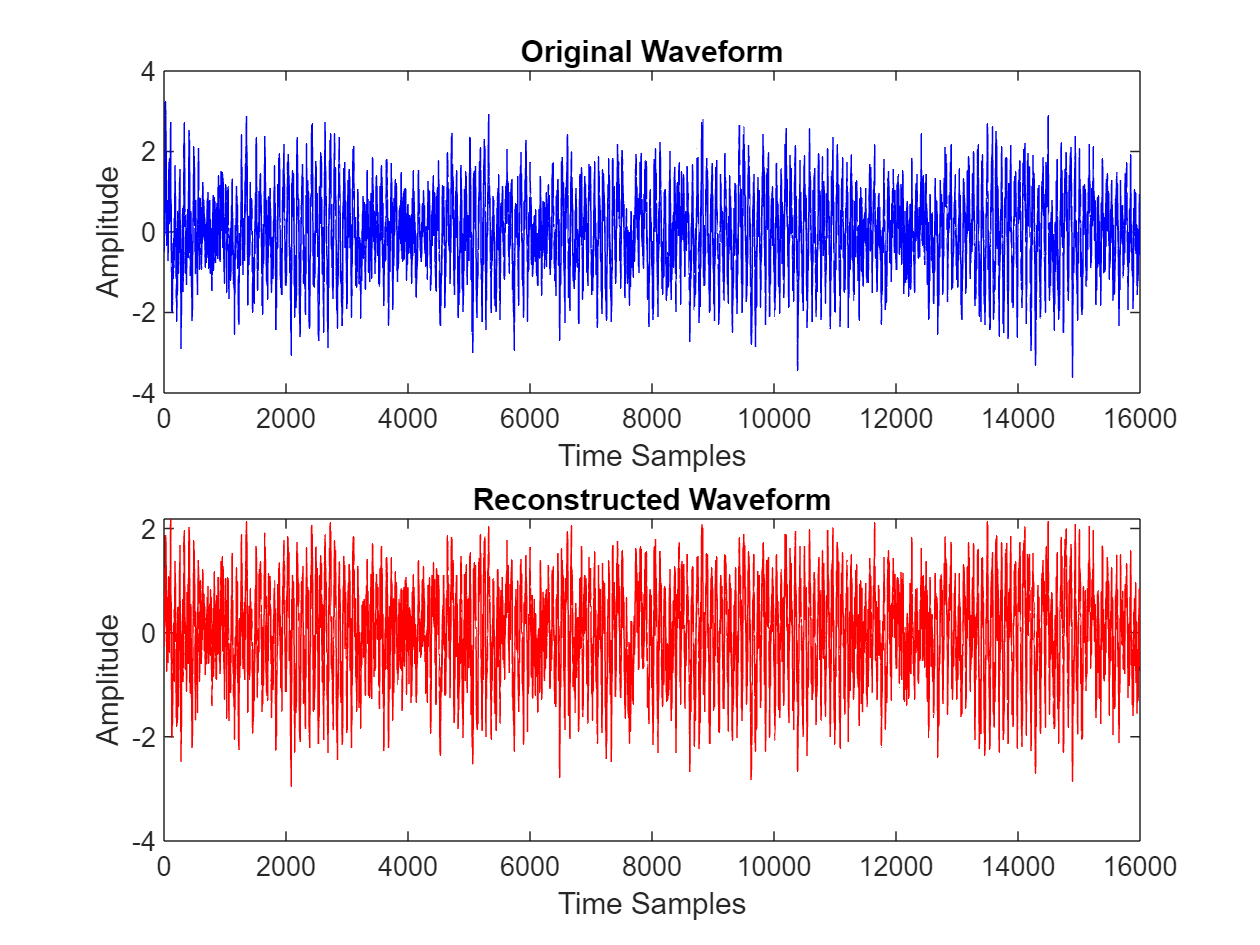

%  Encode the Waveform into Learned Features
encodedFeatures = encode(autoenc1, waveformData);

%  Decode Features Back to Reconstructed Waveform
reconstructedWaveform = predict(autoenc1, waveformData);
%  Select a Sample to Compare
sampleIdx = 1; % Change this to visualize different samples

%  Extract Original and Reconstructed Waveforms
original = waveformData(sampleIdx, :);
reconstructed = reconstructedWaveform(sampleIdx, :);

%  Plot the Waveforms
figure;
subplot(2,1,1);
plot(original, 'b');
title("Original Waveform");
xlabel("Time Samples");
ylabel("Amplitude");

subplot(2,1,2);
plot(reconstructed, 'r');
title("Reconstructed Waveform");
xlabel("Time Samples");
ylabel("Amplitude");

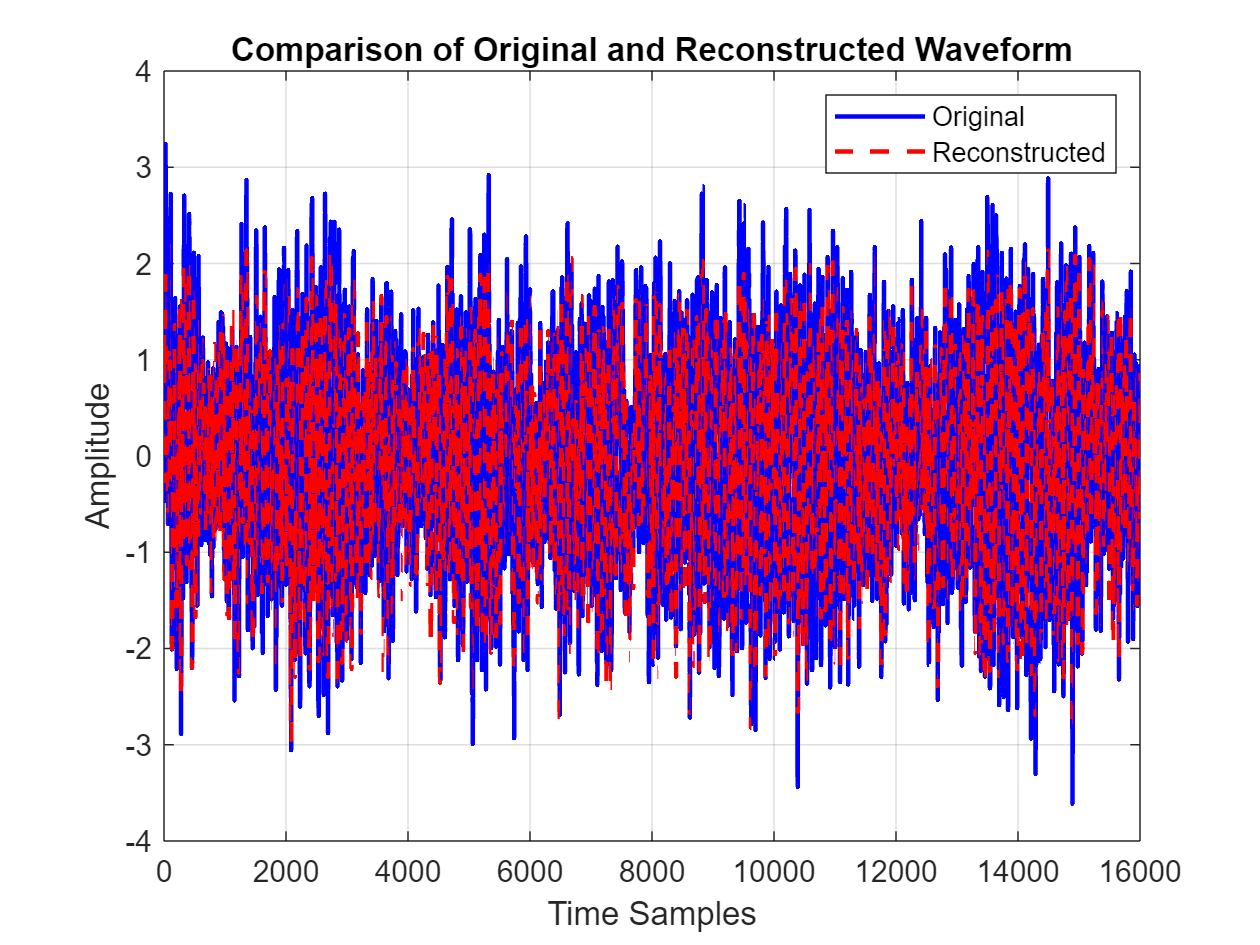


%  Overlay Both for Direct Comparison
figure;
plot(original, 'b', 'LineWidth', 1.5); hold on;
plot(reconstructed, 'r--', 'LineWidth', 1.5);
legend("Original", "Reconstructed");
title("Comparison of Original and Reconstructed Waveform");
xlabel("Time Samples");
ylabel("Amplitude");
grid on;

% Compute Reconstruction Error
mseError = mean((original - reconstructed).^2);
fprintf("Mean Squared Error (MSE) for Sample %d: %.6f\n", sampleIdx, mseError);

Mean Squared Error (MSE) for Sample 1: 0.080069



%  Compute Signal-to-Noise Ratio (SNR)
signalPower = mean(original.^2);
noisePower = mean((original - reconstructed).^2);
snrValue = 10 * log10(signalPower / noisePower);
fprintf("Signal-to-Noise Ratio (SNR) for Sample %d: %.2f dB\n", sampleIdx, snrValue);

Signal-to-Noise Ratio (SNR) for Sample 1: 10.97 dB
